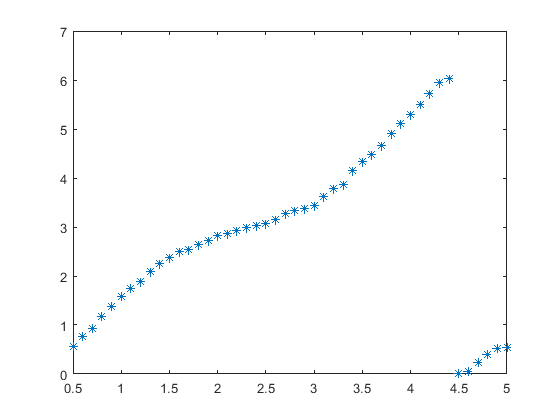

clc
clear 
close all
opengl('save', 'software')
a = (1.045-0.780)*rand() + 0.780;
omega = (2-1.884)*rand() + 1.884;
phi = 2*pi*rand(1,1);
fn =@(t) -a./omega *cos(omega*t+phi)+(2.090-a)*t;
dt =0.1;
t0 = 0.5:dt:5;
E=1e-5;
e = 1e-2;

theta_tiaobian_threshold = 60/360 * 2*pi;%72度为真实跳变

theta = mod(fn(t0) + 0.01*pi*randn(1,length(t0)),2*pi);

plot(t0,theta,"*")

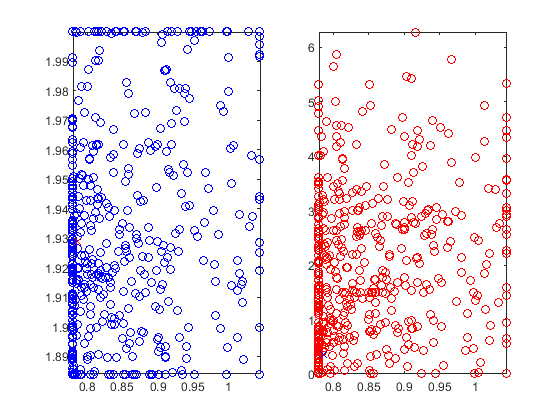

% mean2=theta;
% for i=1:1:length(t0)-4
%     mean2(i+2) = (mean2(i)+mean2(i+1)+mean2(i+3)+mean2(i+4))/4;
% end
% 
% plot(t0, theta, "b*-",t0, mean2, "r*-",t0,fn(t0))
% 
% theta=mean2;
%%预测的函数为diff(t,dt)
% dtheta = diff(theta);
% 
% plot(t0(2:end),dtheta)

maxnum=100;%最大迭代次数
narvs=3;%目标函数的自变量个数
particlesize=500;%粒子群规模
c1=2;%每个粒子的个体学习因子，加速度常数
c2=2;%每个粒子的社会学习因子，加速度常数
w=0.6;%惯性因子
vmax = 1.5;%粒子的最大飞翔速度
v = 1*rand(particlesize,narvs);%粒子飞翔速度
x1= (1.045-0.780)*rand(particlesize,narvs-2)+0.780;%粒子所在位置
x2= (2.000-1.884)*rand(particlesize,narvs-2)+1.884;
x3= 2*pi*rand(particlesize,narvs-2);
x = [x1 x2 x3];
%定义适应度函数

temp = fit(particlesize,x,t0,theta);
personalbest_x=x;
personalbest_faval=temp./length(theta);
[globalbest_faval,i]=min(personalbest_faval);
globalbest_x=personalbest_x(i,:); 
k=1;
ff = zeros(1,maxnum);
figure(1);
h1 = subplot(1,2,1);
h2 = subplot(1,2,2);
best_awp = zeros(1,6);
while (k<=maxnum)

    w = k*(0.9-0.1)/maxnum + 0.1;
	temp=fit(particlesize,x,t0,theta);
    if mod(k,50)==0
        subplot(h1)
        plot(x(:,1),x(:,2),'bo',a,omega,"rx")
        xlim([0.780,1.045])
        ylim([1.884,2.000])
        drawnow;
    end
    if mod(k,50)==0
        subplot(h2)
        plot(x(:,1),x(:,3),'ro',a,phi,"bx")
        xlim([0.780,1.045])
        ylim([0,2*pi])
        drawnow;
    end

	for i=1:particlesize
		if temp(i)<personalbest_faval(i)
			personalbest_faval(i)=temp(i);
			personalbest_x(i,:)=x(i,:);
		end
	end
	[globalbest_faval,i]=min(personalbest_faval);
	globalbest_x=personalbest_x(i,:);
    for i=1:particlesize
		v(i,:)=w*v(i,:)+c1*rand*(personalbest_x(i,:)-x(i,:))...
			+c2*rand*(globalbest_x-x(i,:));
		for j=1:narvs
            if v(i,j)>vmax
				v(i,j)=vmax;
			elseif v(i,j)<-vmax
				v(i,j)=-vmax;
            end
		end
		
        x(i,:)=x(i,:)+v(i,:);
       
        if x(i,1)>1.045
            x(i,1)=1.045;
        end
        if x(i,1)<0.780
            x(i,1)=0.780;
        end        
        if x(i,2)>2.000
            x(i,2)=2.000;
        end
        if x(i,2)<1.884
            x(i,2)=1.884;
        end
        if x(i,3)>2*pi
            x(i,3)=2*pi;
        end
        if x(i,3)<0
            x(i,3)=0;
        end
        
        if abs(globalbest_x(1)-a)<e && best_awp(1)==0
            best_awp(1) = globalbest_x(1);
            best_awp(2) = k;
           
        end
        if abs(globalbest_x(2)-omega)<e && best_awp(3)==0
            best_awp(3) = globalbest_x(2);
            best_awp(4) = k;
        end
        if (abs(globalbest_x(3)-0)<e || abs(globalbest_x(3)-2*pi)<e) && best_awp(5)==0 
            best_awp(5) = globalbest_x(3);
            best_awp(6) = k;
        end
    end
    

%     if mod(k,500)==0
%         disp(globalbest_faval);
%     end
    ff(k)=globalbest_faval;
    if globalbest_faval<E
        break
    end
%       figure(1)
%       for i= 1:particlesize
%       plot(x(i,1),x(i,2),'*')
%       end
	k=k+1;
end


disp(best_awp);

    0.7872    1.0000    1.9200    1.0000         0         0




xbest=globalbest_x;
figure;
set(gcf,'color','white');
plot(1:length(ff),ff)
disp([globalbest_faval])

    0.1721



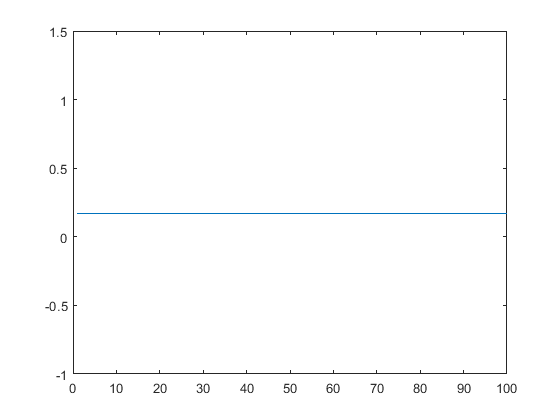

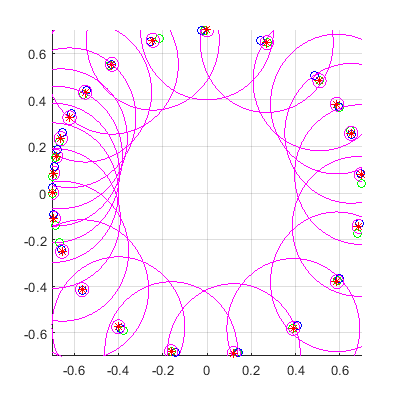

fs_solve=@(x,t)mod((-x(1)./x(2) *cos(x(2)*t+x(3))+(2.090-x(1))*t),2*pi);
theta_solve = fs_solve(xbest,t0);
theta_vision = theta;
theta = fn(t0);
figure('Position', [400, 400, 400, 400]);
VMSE = 0;
TMSE = 0;
TVMSE = 0;
GMSE = 0;
alpha = 0.3;
r1 = 0.03;
r2 = 0.3;
for i = 1:1:length(theta)
    dx = 0.7*cos(theta_vision(i))-0.7*cos(theta_solve(i));
    dy = 0.7*sin(theta_vision(i))-0.7*sin(theta_solve(i));
    tdx = 0.7*cos(theta(i))-0.7*cos(theta_solve(i));
    tdy = 0.7*sin(theta(i))-0.7*sin(theta_solve(i));

    gt_x = 0.7*(alpha*cos(theta_vision(i))+(1-alpha)*cos(theta_solve(i)));
    gt_y = 0.7*(alpha*sin(theta_vision(i))+(1-alpha)*sin(theta_solve(i)));
    gt_dx = gt_x-0.7*cos(theta(i));
    gt_dy = gt_y-0.7*sin(theta(i));
    GMSE = (gt_dx^2+gt_dy^2)^0.5+GMSE;
    VMSE = (dx^2+dy^2)^0.5+VMSE;
    TMSE = (tdx^2+tdy^2)^0.5+TMSE;
    TVMSE = ((tdx-dx)^2+(tdy-dy)^2)^0.5+TVMSE;
    true_x = 0.7*cos(theta(i));
    true_y = 0.7*sin(theta(i));
    hold on
    grid on
    if mod(i,2)==0
    plot(0.7*cos(theta_vision(i)),0.7*sin(theta_vision(i)),"gO")
    plot(0.7*cos(theta_solve(i)),0.7*sin(theta_solve(i)),'bo')
    plot(0.7*cos(theta(i)),0.7*sin(theta(i)),'r*')
    rectangle('Position',[true_x-r1,true_y-r1,2*r1,2*r1],'Curvature',[1,1],'EdgeColor','m')
    rectangle('Position',[true_x-r2,true_y-r2,2*r2,2*r2],'Curvature',[1,1],'EdgeColor','m')

    xlim([-0.7,0.7])
    ylim([-0.7,0.7])
    pause(0.1);
    drawnow
    end
end

% 0.3 m
VMSE = VMSE/length(theta);% 观测与预测
TMSE = TMSE/length(theta);% 真实函数与预测
GMSE = GMSE/length(theta);% 真实与加权
TVMSE = TVMSE/length(theta);% 真实与观测
disp(['VMSE:' num2str(VMSE*1000) 'mm'])

VMSE:26.2085mm


disp(['TMSE:' num2str(TMSE*1000) 'mm'])

TMSE:17.5862mm


disp(['GMSE:' num2str(GMSE*1000) 'mm'])

GMSE:12.7469mm


disp(['TVMSE:' num2str(TVMSE*1000) 'mm'])

TVMSE:17.4536mm


% 
% %% 加权系数判断
% 
% BestGMSE = 100;
% bestalpha = 0;
% for alpha=0:0.05:1
%     for i = 1:1:length(theta)
%         gt_x = 0.7*(alpha*cos(theta_vision(i))+(1-alpha)*cos(theta_solve(i)));
%         gt_y = 0.7*(alpha*sin(theta_vision(i))+(1-alpha)*sin(theta_solve(i)));
%         gt_dx = gt_x-0.7*cos(theta(i));
%         gt_dy = gt_y-0.7*sin(theta(i));
%         GMSE = (gt_dx^2+gt_dy^2)^0.5+GMSE;
%     end 
%     GMSE = GMSE/length(theta);
%     if GMSE<BestGMSE
%         BestGMSE = GMSE;
%         bestalpha = alpha;
%     end
% end
% disp(['BestGMSE: ' num2str(BestGMSE*1000) 'mm'])
% disp(['Bestalpha: ' num2str(bestalpha)])